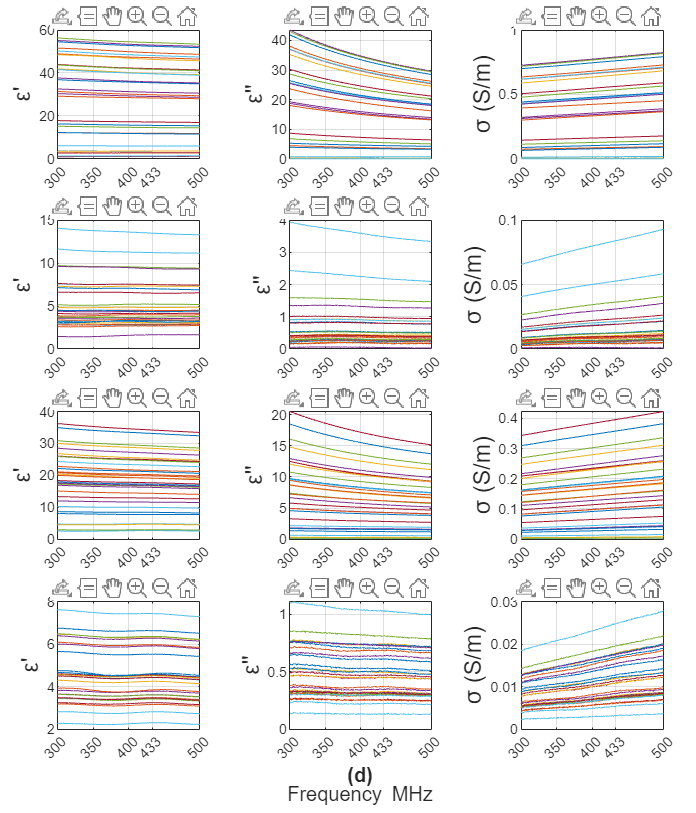

% DirectoryName = "C:\Users\chase\Documents\22-23 Senior Project M1 Research\Summer24_Measurements\Pork_Summer24_3\Pork\";
% DirectoryName2 = "C:\Users\chase\Documents\22-23 Senior Project M1 Research\Summer24_Measurements\Pork_Summer24_3\Pork+Fat\";
% DirectoryName3 = "C:\Users\chase\Documents\22-23 Senior Project M1 Research\Summer24_Measurements\Pork_Summer24_3\Compressed_Pork\";
% DirectoryName4 = "C:\Users\chase\Documents\22-23 Senior Project M1 Research\Summer24_Measurements\Pork_Summer24_3\Compressed_Pork+Fat\";

DirectoryName = "C:\Users\chase\Documents\22-23 Senior Project M1 Research\Spring 24 Measurements\Dielectric Measurements\New Pork\Pork\";
DirectoryName2 = "C:\Users\chase\Documents\22-23 Senior Project M1 Research\Spring 24 Measurements\Dielectric Measurements\New Pork\Pork+Fat\";
DirectoryName3 = "C:\Users\chase\Documents\22-23 Senior Project M1 Research\Spring 24 Measurements\Dielectric Measurements\Compressed Pork\Pork\";
DirectoryName4 = "C:\Users\chase\Documents\22-23 Senior Project M1 Research\Spring 24 Measurements\Dielectric Measurements\Compressed Pork\Pork+Fat\";

%paste in your csv or xlsx files here:

FileNames = [
    "PF T1.xlsx";
    "PF T2.xlsx";
    "PF T3.xlsx";
    "PF T4.xlsx";
    "PF T5.xlsx";
    "PF T6.xlsx";
    "PF T7.xlsx";
    "PF T8.xlsx";
    "PF T9.xlsx";
    "PF T10.xlsx";
    "PF T11.xlsx";
    "PF T12.xlsx";
    "PF T13.xlsx";
    "PF T14.xlsx";
    "PF T15.xlsx";
    "PF T16.xlsx";
    "PF T17.xlsx";
    "PF T18.xlsx";
    "PF T19.xlsx";
    "PF T20.xlsx";
    "PF T21.xlsx";
    "PF T22.xlsx";
    "PF T23.xlsx";
    "PF T24.xlsx";
    "PF T25.xlsx";
    "PF T26.xlsx";
    "PF T27.xlsx";
    "PF T28.xlsx";
    "PF T29.xlsx";
    "PF T30.xlsx";
    ];

% FileNames = [
%     "PF T1.csv";
%     "PF T2.csv";
%     "PF T3.csv";
%     "PF T4.csv";
%     "PF T5.csv";
%     "PF T6.csv";
%     "PF T7.csv";
%     "PF T8.csv";
%     "PF T9.csv";
%     "PF T10.csv";
%     "PF T11.csv";
%     "PF T12.csv";
%     "PF T13.csv";
%     "PF T14.csv";
%     "PF T15.csv";
%     "PF T16.csv";
%     "PF T17.csv";
%     "PF T18.csv";
%     "PF T19.csv";
%     "PF T20.csv";
%     "PF T21.csv";
%     "PF T22.csv";
%     "PF T23.csv";
%     "PF T24.csv";
%     "PF T25.csv";
%     "PF T26.csv";
%     "PF T27.csv";
%     "PF T28.csv";
%     "PF T29.csv";
%     "PF T30.csv";
%     "PF T31.csv";
%     "PF T32.csv";
%     "PF T33.csv";
%     "PF T34.csv";
%     "PF T35.csv";
%     "PF T36.csv";
%     "PF T37.csv";
%     "PF T38.csv";
%     "PF T39.csv";
%     "PF T40.csv";
%     "PF T41.csv";
%     "PF T42.csv";
%     "PF T43.csv";
%     "PF T44.csv";
%     "PF T45.csv";
%     "PF T46.csv";
%     "PF T47.csv";
%     "PF T48.csv";
%     "PF T49.csv";
%     "PF T50.csv";
%     "PF T51.csv";
%     "PF T52.csv";
%     "PF T53.csv";
%     "PF T54.csv";
%     "PF T55.csv";
%     "PF T56.csv";
%     "PF T57.csv";
%     "PF T58.csv";
%     "PF T59.csv";
%     "PF T60.csv";
%     "PF T61.csv";
%     "PF T62.csv";
%     "PF T63.csv";
%     "PF T64.csv";
%     "PF T65.csv";
%     "PF T66.csv";
%     "PF T67.csv";
%     "PF T68.csv";
%     "PF T69.csv";
%     "PF T70.csv";
%     ];

FileCount = 1:30;

% FileCount = 1:70;

%Epsilon Chars
epsilon_p = char(949) + "'";
epsilon_pp = char(949) + "''";
sigma_char = char(963) + " (S/m)";


figure('Position', [1, 1, 600, 700])
t = tiledlayout(4,3,'TileSpacing','compact','Padding','compact');
% xlabel(t, sprintf('Frequency {MHz}\n \\bf (a) '),'interpreter','tex', 'FontSize', 12);
xlabel(t, sprintf('Frequency {MHz}'),'interpreter','tex', 'FontSize', 12);

% Tile 1
nexttile
epsilonPrime(DirectoryName, FileNames, FileCount);
%ylabel(' $\varepsilon^{\prime}$ ','interpreter','latex', "FontSize", 18);
ylabel(epsilon_p, "FontSize", 14);

%Tile 2
nexttile
epsilonDoublePrime(DirectoryName, FileNames, FileCount);
% ylabel(' $\varepsilon^{\prime \prime}$ ','interpreter','latex', "FontSize", 18);
ylabel(epsilon_pp, "FontSize", 14);
xlabel(" (a) ", 'FontWeight', 'bold', 'FontSize', 12);

%Tile 3
nexttile
conductivity(DirectoryName, FileNames, FileCount);
ylabel(sigma_char, "FontSize", 14);

% figure('Position', [1, 1, 600, 250])
% t = tiledlayout(1,3,'TileSpacing','compact','Padding','compact');
% xlabel(t, sprintf('Frequency {MHz}\n \\bf (b) '),'interpreter','tex', 'FontSize', 12);

% Tile 1
nexttile
epsilonPrime(DirectoryName2, FileNames, FileCount);
ylabel(epsilon_p, "FontSize", 14);

%Tile 2
nexttile
epsilonDoublePrime(DirectoryName2, FileNames, FileCount);
ylabel(epsilon_pp, "FontSize", 14);
xlabel(" (b) ", 'FontWeight', 'bold', 'FontSize', 12);

%Tile 3
nexttile
conductivity(DirectoryName2, FileNames, FileCount);
ylabel(sigma_char, "FontSize", 14);

% figure('Position', [1, 1, 600, 250])
% t = tiledlayout(1,3,'TileSpacing','compact','Padding','compact');
% xlabel(t, sprintf('Frequency {MHz}\n \\bf (c) '),'interpreter','tex', 'FontSize', 12);

% Tile 1
nexttile
epsilonPrime(DirectoryName3, FileNames, FileCount);
ylabel(epsilon_p, "FontSize", 14);

%Tile 2
nexttile
epsilonDoublePrime(DirectoryName3, FileNames, FileCount);
ylabel(epsilon_pp, "FontSize", 14);
xlabel(" (c) ", 'FontWeight', 'bold', 'FontSize', 12);

%Tile 3
nexttile
conductivity(DirectoryName3, FileNames, FileCount);
ylabel(sigma_char, "FontSize", 14);

% figure('Position', [1, 1, 600, 250])
% t = tiledlayout(1,3,'TileSpacing','compact','Padding','compact');
% xlabel(t, sprintf('Frequency {MHz}\n \\bf (d) '),'interpreter','tex', 'FontSize', 12);

% Tile 1
nexttile
epsilonPrime(DirectoryName4, FileNames, FileCount);
ylabel(epsilon_p, "FontSize", 14);

%Tile 2
nexttile
epsilonDoublePrime(DirectoryName4, FileNames, FileCount);
ylabel(epsilon_pp, "FontSize", 14);
xlabel(" (d) ", 'FontWeight', 'bold', 'FontSize', 12);

%Tile 3
nexttile
conductivity(DirectoryName4, FileNames, FileCount);
ylabel(sigma_char, "FontSize", 14);

function epsilonPrime(DirectoryName, FileNames, FileCount) %Real

    for loopFiles = FileCount
        VNA_Zdata = readmatrix(strcat(DirectoryName,FileNames(loopFiles,:)));
        Freq = VNA_Zdata(:,1);
        MHz_PlotFreq = Freq/1e6;
        epsP = VNA_Zdata(:,2);
        plot(MHz_PlotFreq, epsP)
        xticks([300 350 400 433 500])
        grid on;
        hold on;
    end
end

function epsilonDoublePrime(DirectoryName, FileNames, FileCount) %Imaginary

    for loopFiles = FileCount
        VNA_Zdata = readmatrix(strcat(DirectoryName,FileNames(loopFiles,:)));
        Freq = VNA_Zdata(:,1);
        MHz_PlotFreq = Freq/1e6;
        epsPP = VNA_Zdata(:,3);
        plot(MHz_PlotFreq, epsPP)
        % xlabel(" Frequency [ MHz ] ", 'FontSize', 11);
        % ylabel(" Magnitude { dB } ", "FontSize", 11);           
        xticks([300 350 400 433 500])
        grid on;
        hold on;
    end
end

function [sigma, w] = conductivity(DirectoryName, FileNames, FileCount) %Imaginary

eps_o = 8.854*10^-12;

    for loopFiles = FileCount
        VNA_Zdata = readmatrix(strcat(DirectoryName,FileNames(loopFiles,:)));
        Freq = VNA_Zdata(:,1);
        MHz_PlotFreq = Freq/1e6;
        epsPP = VNA_Zdata(:,3);
        w = 2*pi.*Freq;
        sigma = epsPP.*w*eps_o;
        plot(MHz_PlotFreq, sigma);
        % xlabel(" Frequency [ MHz ] ", 'FontSize', 11);
        % ylabel(" Magnitude { dB } ", "FontSize", 11);           
        xticks([300 350 400 433 500]);
        grid on;
        hold on;
    end
end